# Selección de señales

clear all
close all

load('E:\TFG_Workspace\Sources\MATfiles\MAT files\Participant1\Processed_Data.mat')
load('E:\TFG_Workspace\Sources\MATfiles\MAT files\Participant1\Raw_Data.mat')

par = 1;
vel = "V1"; 
trial = 1;
mus = "L_TA"; % tibial anterior izquierdo


Subject = "Subject" + num2str(par) + "_raw";

eval("raw_time = " + Subject + "." + (vel) + ".EMG{" + num2str(trial) + ", 2}.Time;");
eval("raw_data = " + Subject + "." + (vel) + ".EMG{" + num2str(trial) + ", 2}." + (mus) + ";");

% CUANTIFICACIÓN
Q_data = quantizer('Mode','fixed', 'RoundMode','ceil', 'OverflowMode','saturate', 'Format',[24+1 24]);
Q_suma = quantizer('Mode','fixed', 'RoundMode','ceil', 'OverflowMode','saturate', 'Format',[24+1 24-8]);

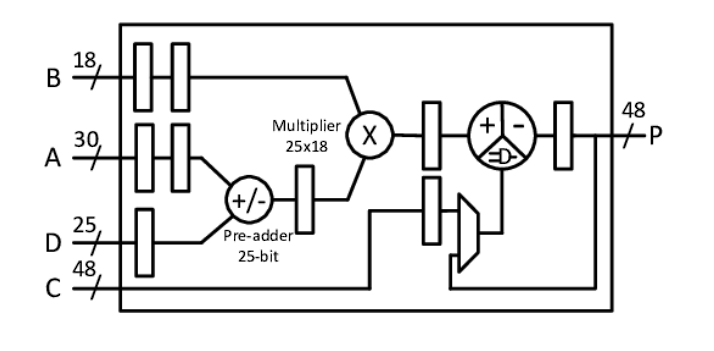

# Implementación de filtro

order = 255;
G = 100;
x = abs(raw_data);
xq = quantize(Q_data,x);


win_size = order+1;
signal_size = length(xq);

% inicializacion de vector de salida
y = zeros(1,signal_size);

% registro de desplazamiento que conforma el filtro
shift_reg = zeros(1,win_size);

% bucle de muestra de entrada y desplazamiento del registro + promedio del
% registro
for n=1:signal_size
    shift_reg(2:end) = shift_reg(1:end-1);
    shift_reg(1) = xq(n);
    y(n) = 0;
    for i=1:win_size
        y(n) = quantize(Q_suma,y(n)+shift_reg(i));
    end
    y(n) = y(n)/win_size;
end

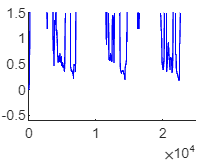

figure
hold on;
plot(y*G,'Color','b')
xlim([0 25000])
ylim([-0.6 1.5]);